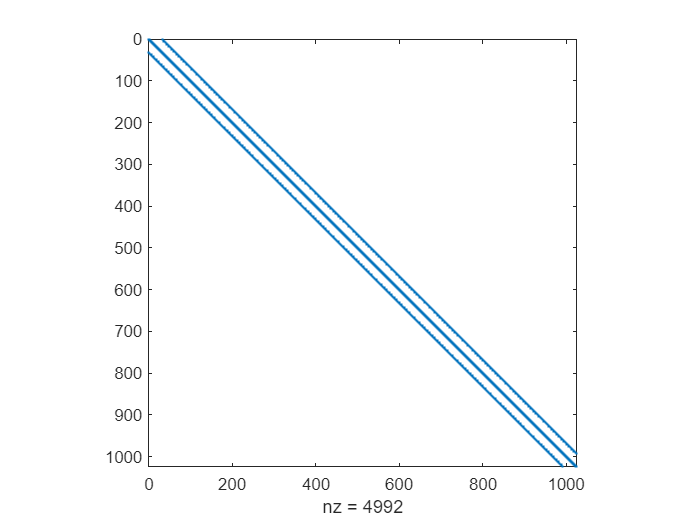

% belso pontok szama
N = 32;

% lepeshossz
h = 1/(N+1);

e = ones(N,1);
E = spdiags([-1*e,6*e,-1*e],[-1,0,1],N,N);
F = -1*speye(N);

Tmp1 = spdiags([e,e],[-1,1],N,N);
B_tilde = kron(speye(N),E) + kron(Tmp1,F);
spy(B_tilde);

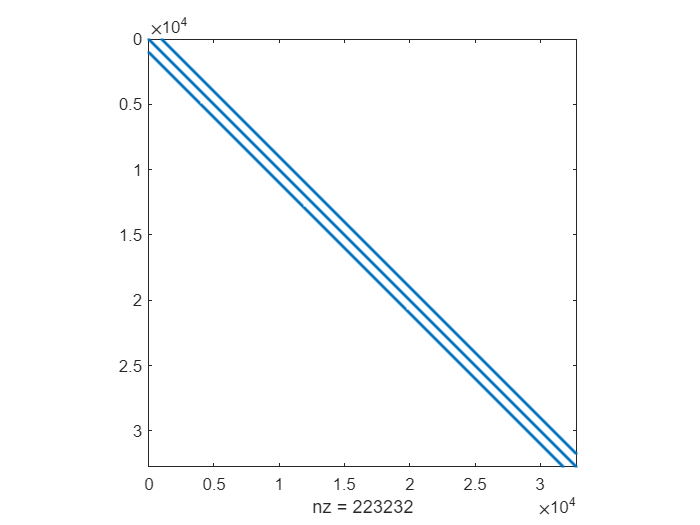

I = speye(N^2);
A_h = 1/h^2 * (kron(speye(N),B_tilde) + kron(Tmp1,(-1)*I));

spy(A_h)


%Numerikusan közelített értékek a rácspontokban
% 3d
[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:1-h);
tmp=sin(xi*pi).*sin(yj*pi).*sin(zk*pi);
size(tmp)

ans =     32    32    32


f=3*pi^2*reshape(pagetranspose(tmp),N^3,1);

% numerikusan kozelitett ertekek
y = A_h\f;

ybrick=reshape(y,N,N,N);
ybrick = pagetranspose(ybrick);
size(ybrick)

ans =     32    32    32


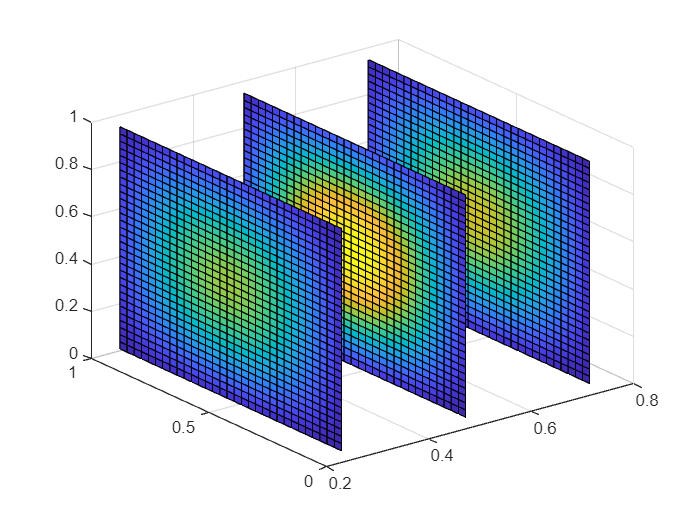



xslice = [8*h,16*h,24*h];   
yslice = [];
zslice = [];
slice(xi,yj,zk,ybrick,xslice,yslice,zslice)

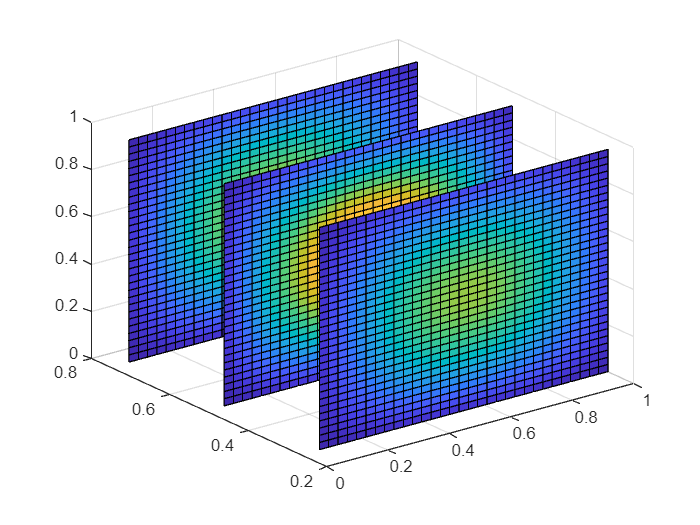

xslice = [];   
yslice = [8*h,16*h,24*h]; 
zslice = [];
slice(xi,yj,zk,ybrick,xslice,yslice,zslice)

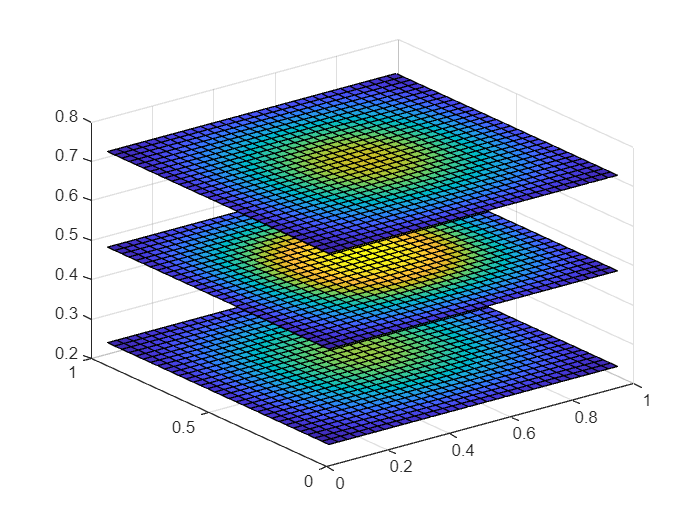


xslice = [];   
yslice = []; 
zslice = [8*h,16*h,24*h];
slice(xi,yj,zk,ybrick,xslice,yslice,zslice)